% Импортируйте данные из csv-файлов
spectra = importdata('spectra.csv');
lambdaStart = importdata('lambda_start.csv');
lambdaDelta = importdata('lambda_delta.csv');
starNames = importdata('star_names.csv');
% Определите константы
LambdaPr = 656.28; %нм
speedOfLight = 299792.458; %км/c

% Определите диапазон длин волн
nObs = size(spectra, 1)

nObs = 357

LambdaEnd = lambdaStart + (nObs - 1)*lambdaDelta

LambdaEnd = 679.8600

lambda = (lambdaStart : lambdaDelta : LambdaEnd)'

lambda =   630.0200
  630.1600
  630.3000
  630.4400
  630.5800
  630.7200
  630.8600
  631.0000
  631.1400
  631.2800


nNames = size(starNames,1)

nNames = 7

% Рассчитайте скорости звезд относительно Земли
i = 1

i = 1

sHaVec = linspace(0,0,nNames);
indVec = linspace(0,0,nNames);
speed = linspace(0,0,nNames);
while i <= nNames
    s = spectra(:, i)
    [sHa, ind] = min(s)
    sHaVec(i) = sHa
    indVec(i) = ind
    LambdaHa = lambda(ind)
    speed(i) = (LambdaHa / LambdaPr - 1) * speedOfLight
    i = i+1
end

s = 	1.0e+-12 *

    0.3088
    0.3136
    0.3105
    0.3076
    0.3088
    0.3105
    0.3122
    0.3101
    0.3078
    0.3047


sHa = 1.6340e-13

ind = 188

sHaVec = 	1.0e+-12 *

    0.1634         0         0         0         0         0         0


indVec =    188     0     0     0     0     0     0


LambdaHa = 656.2000

speed =   -36.5445         0         0         0         0         0         0


i = 2

s = 	1.0e+-12 *

    0.1340
    0.1338
    0.1347
    0.1357
    0.1354
    0.1343
    0.1335
    0.1325
    0.1335
    0.1329


sHa = 7.2400e-14

ind = 187

sHaVec = 	1.0e+-12 *

    0.1634    0.0724         0         0         0         0         0


indVec =    188   187     0     0     0     0     0


LambdaHa = 656.0600

speed =   -36.5445 -100.4973         0         0         0         0         0


i = 3

s = 	1.0e+-13 *

    0.5981
    0.6074
    0.6176
    0.6252
    0.6271
    0.6221
    0.6192
    0.6200
    0.6261
    0.6249


sHa = 3.1440e-14

ind = 188

sHaVec = 	1.0e+-12 *

    0.1634    0.0724    0.0314         0         0         0         0


indVec =    188   187   188     0     0     0     0


LambdaHa = 656.2000

speed =   -36.5445 -100.4973  -36.5445         0         0         0         0


i = 4

s = 	1.0e+-13 *

    0.8919
    0.8981
    0.9152
    0.9311
    0.9355
    0.9321
    0.9286
    0.9247
    0.9240
    0.9177


sHa = 5.3640e-14

ind = 189

sHaVec = 	1.0e+-12 *

    0.1634    0.0724    0.0314    0.0536         0         0         0


indVec =    188   187   188   189     0     0     0


LambdaHa = 656.3400

speed =   -36.5445 -100.4973  -36.5445   27.4083         0         0         0


i = 5

s = 	1.0e+-12 *

    0.1088
    0.1084
    0.1104
    0.1124
    0.1122
    0.1136
    0.1138
    0.1130
    0.1124
    0.1108


sHa = 6.8980e-14

ind = 189

sHaVec = 	1.0e+-12 *

    0.1634    0.0724    0.0314    0.0536    0.0690         0         0


indVec =    188   187   188   189   189     0     0


LambdaHa = 656.3400

speed =   -36.5445 -100.4973  -36.5445   27.4083   27.4083         0         0


i = 6

s = 	1.0e+-12 *

    0.1625
    0.1630
    0.1615
    0.1586
    0.1574
    0.1589
    0.1611
    0.1607
    0.1593
    0.1582


sHa = 9.8010e-14

ind = 191

sHaVec = 	1.0e+-12 *

    0.1634    0.0724    0.0314    0.0536    0.0690    0.0980         0


indVec =    188   187   188   189   189   191     0


LambdaHa = 656.6200

speed =   -36.5445 -100.4973  -36.5445   27.4083   27.4083  155.3139         0


i = 7

s = 	1.0e+-13 *

    0.3918
    0.3821
    0.3712
    0.3776
    0.3910
    0.3955
    0.4023
    0.3986
    0.3874
    0.3793


sHa = 2.2140e-14

ind = 185

sHaVec = 	1.0e+-12 *

    0.1634    0.0724    0.0314    0.0536    0.0690    0.0980    0.0221


indVec =    188   187   188   189   189   191   185


LambdaHa = 655.7800

speed =   -36.5445 -100.4973  -36.5445   27.4083   27.4083  155.3139 -228.4029


i = 8

% Постройте график
fg1 = figure;
i = 1

i = 1

while i <= nNames
    hold on
    s = spectra(:, i)
    if speed(i) > 0
        plot(lambda, s, "-", 'LineWidth', 3)
    else
        plot(lambda, s, "--", 'LineWidth', 1)
    end
    xlabel('Длина волны, нм')
    ylabel(['Интенсивность, эрг/см^2/с/', char(197)])
    title('Спектры звезд')
    grid on

    i = i + 1 
end

s = 	1.0e+-12 *

    0.3088
    0.3136
    0.3105
    0.3076
    0.3088
    0.3105
    0.3122
    0.3101
    0.3078
    0.3047


i = 2

s = 	1.0e+-12 *

    0.1340
    0.1338
    0.1347
    0.1357
    0.1354
    0.1343
    0.1335
    0.1325
    0.1335
    0.1329


i = 3

s = 	1.0e+-13 *

    0.5981
    0.6074
    0.6176
    0.6252
    0.6271
    0.6221
    0.6192
    0.6200
    0.6261
    0.6249


i = 4

s = 	1.0e+-13 *

    0.8919
    0.8981
    0.9152
    0.9311
    0.9355
    0.9321
    0.9286
    0.9247
    0.9240
    0.9177


i = 5

s = 	1.0e+-12 *

    0.1088
    0.1084
    0.1104
    0.1124
    0.1122
    0.1136
    0.1138
    0.1130
    0.1124
    0.1108


i = 6

s = 	1.0e+-12 *

    0.1625
    0.1630
    0.1615
    0.1586
    0.1574
    0.1589
    0.1611
    0.1607
    0.1593
    0.1582


i = 7

s = 	1.0e+-13 *

    0.3918
    0.3821
    0.3712
    0.3776
    0.3910
    0.3955
    0.4023
    0.3986
    0.3874
    0.3793


i = 8

text(lambdaStart + 5, max(s)*6.5, 'Соколов Роман Б01-008')
legend(starNames)
set(fg1, 'visible', 'on');
movaway = starNames(speed > 0)

movaway = 3×1 cell array
    {'HD5211' }
    {'HD56030'}
    {'HD94028'}


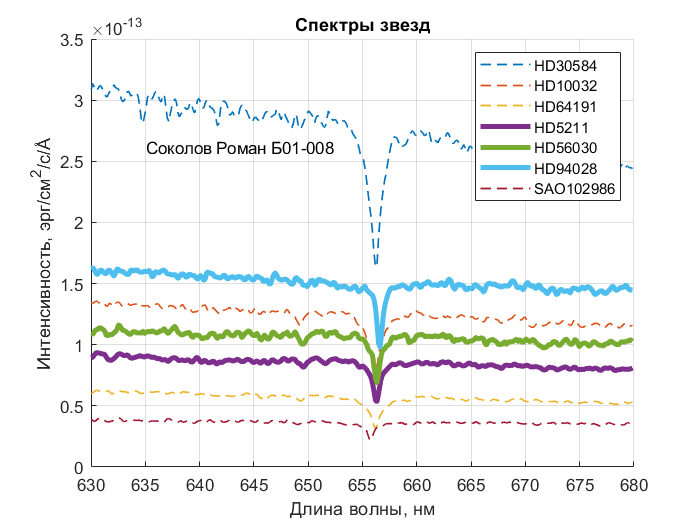

% Сохраните график
saveas(fg1, 'spectra', 'png')